# Model fitting and validation for Hubei, China

The following document presents the implemented code to fit and validate a discrete compartmental model that describes the COVID-19 transmission, specifically for the Hubei province. Note that we used the GSUA_CSB toolbox available in [GitHub](https://github.com/drojasd/GSUA-CSB).

## 1. Load the real data

First, we load the real data that is actual, deads, and recovered cases. Note that we can define the actual cases as follow

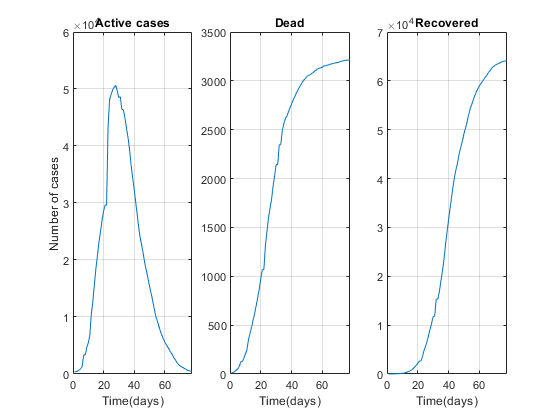

% addpath Tool/
addpath C:\Users\User\Desktop\Covid-19\Covmat\ChimeraModelForCovid19-main\Model
addpath C:\Users\User\Desktop\Covid-19\Covmat\ChimeraModelForCovid19-main\Data
load('China.mat');
Extension = length(ActualCases);

ydata = zeros(3,Extension);    
ydata(1,:) = ActualCases;
ydata(2,:) = Dead;
ydata(3,:) = Recovered;

figure
subplot(1,3,1)
plot(ActualCases)
xlabel('Time(days)')
ylabel('Number of cases')
title('Active cases')
grid on

subplot(1,3,2)
plot(Dead)
xlabel('Time(days)')
title('Dead')
grid on

subplot(1,3,3)
plot(Recovered)
xlabel('Time(days)')
title('Recovered')
grid on

We take this data from [Github](https://github.com/CSSEGISandData/COVID-19) according to [1], from January 21 to April 8, 2020.

**Reference:**

[1]  E. Dong,  H. Du,  L. Gardner,  An interactive web-based dashboard totrack COVID-19 in real time,  The Lancet Infectious Diseases 20 (2020) 533–534.

## 2. Model definition 

First, we define the factor (initial values and parameters) names followed by the model outputs.

VarNames={'N_0','E_0','P_0','J_1','J_{L}','D','R_j','RJ_L'};

OutNames={'S_f','S_q','E_f','E_q','L_f','L_q','H_f','H_q','J','D',...
        'R','T','RJH','RJL','RJ','Tot','JH','JL','J_{~P}','J_{P}','S in','R in','S in','P in','P in','S out','R out','S out','P out','P out'};

ParNames={'\beta_L','\beta_T', '\beta_P', '\phi_{EP}',...
            '\lambda_{fq}', '\vartheta_E','\gamma_L', 'k_L',...
            'k_P', '\phi_T','\lambda_{qf}', '\psi_e', '\phi_{PH}',...
            '\delta','m','\eta_L', '\vartheta_P','\gamma_H', 'z',...
            '\phi_{PL}','\eta_\vartheta','nons','a_L','b_L',...
            'a_\mu','b_\mu','\mu','a_H','b_H','\nu','time'};

FullNames = [VarNames,ParNames];

ModelName = 'ChimeraModel';

Then, we define the interval values for model factors; their values are according to the parameter nature and some studies in literature, for more information about it, see the main paper document.

Range1 = [
    0 0;            % N_0
    0 2000;                 % E^2_0
    0 400;                  % P_0
    ydata(1,1) ydata(1,1);  % J_1
    0 0;                    % J_L
    ydata(2,1) ydata(2,1);  % D
    ydata(3,1) ydata(3,1);  % R_j
    0 0;                    % RJ_L
    ];

Range2=[
    0.7 0.9;    % beta_L
    0   1;      % beta_T          
    0.2 0.6;    % beta_P
    0	8;      % phi_{EP}
    0	1;      % lambda_{fq}
    0	1;      % vartheta_E
    0   1;      % gamma_L
    1   10;     % k_L
    1   1;      % k_P
    1	8;      % phi_T
    0	1;      % lambda_{qf}
    0	0;      % psi_e
    0	3;      % phi_{PH}
    0   0.15;   % delta
    0   0;      % Migration input
    0   1;      % eta_L
    0   1;      % vartheta_P
    0   1;      % gamma_H 
    0   30;     % z 
    0   3;      % phi_{PL}
    0   1;      % eta_vartheta
    0   0;      % nons
    1   15;     % a_L
    1   15;     % b_L
    1   15;     % a_mu
    1   15;     % b_mu
    0   1;      % mu
    1   15;     % a_H
    1   15;     % b_H
    0  500;     % nu
    41  41      % m
    ];

RangeT = [Range1; Range2];

Finally, we define the real data domain

D = length(ydata(1,:));
Domain = [0 D-1];
xdata = 0:D-1;
opt=mdistrib(15000,0.5,0.5,D,1);

and create the struture data that manage the model simulations, estimations, and other methodologies

[T,~] = gsua_dataprep(ModelName,RangeT,'domain',Domain,'names',FullNames,'out_names',OutNames,'opt',opt);

Setting environment to work with user-defined function


## **3. Parameter estimation**

Because of the nature of real data (the presence of three curves to fit the model), we perform multi-objective optimization to estimate the model factors. So, we select the input numbers to fit with real data: **9:** actual cases; **10:** Dead cases; **15:** Identified recovered cases.

T.Properties.CustomProperties.output = [1:30];
gsua_eval(T.Nominal,T,xdata)

Then, we define the optimization options according to the researcher’s necessities. For COVID-19 model, the estimation options are as follows

Solver='fmincon';
    
Opt = optimoptions('fmincon','UseParallel',false,'MaxFunctionEvaluations',30000, ...
    'MaxIterations', 10000, 'Display','off');

We develop a code that saves those estimations which are less than the pre-defined cost function value. Thus, we perform an unknown number of parameter estimations until obtaining N that do not beat this pre-defined value.

N = 9000;                   % Number of estimations
Best = zeros(size(T,1),N);  % Matrix that saves factor's estimated values
IpBest = Best;              % Matrix that saves optimization method initial point
Residual = zeros(1,N);      % Vector that saves estimations cost function value
ResBase = 6e-2;             % Pre-defined cost function value

parfor i = 1:N
    ResTemp = 5e8;
    while ResTemp > ResBase
        [T_est, ResTemp, IP] = gsua_pe(T,xdata,ydata,...
            'solver',Solver,'N',1,'opt',Opt,'save',false);
    end
    IpBest(:,i) = IP;
    Best(:,i) = T_est.Estfmincon;
    Residual(i) = ResTemp;
    i
end

%Sort the estimated values according its cost function value
[Residual, Idx] = sort(Residual);
T.Est = Best(:, Idx);
IpBest = IpBest(:,Idx);

gsua_save(T)

movefile("portable.mat", "Results/ChinaResults/ChinaEstimations.mat");
save('Results/ChinaResults/ChinaEstiamtionsData.mat',...
    'ydata','Residual','IpBest')

Load and plot all factor families estimated in the previous step.

load('Results/ChinaResults/ChinaEstimations.mat')
load('Results/ChinaResults/ChinaEstiamtionsData.mat')
T_est = gsua_load(T);

Setting environment to work with user-defined function


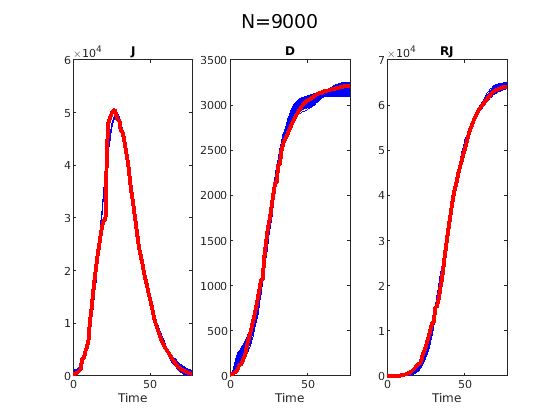

gsua_eval(T.Est,T_est,xdata,ydata);

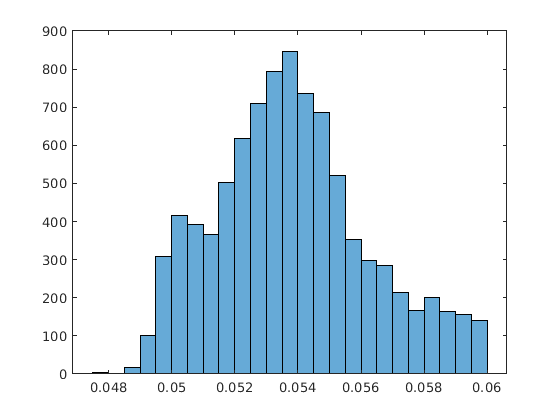

figure
histogram(Residual)

Now, we can filter more the resulted estimations and select a defined number of families with the smallest cost function value. 

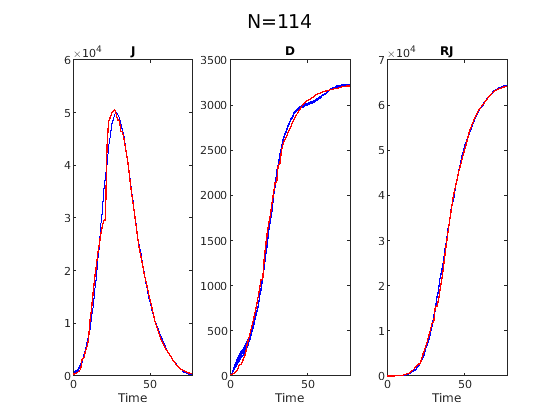

Filtered = 114;
gsua_eval(T.Est(:,1:Filtered),T_est,xdata,ydata);

## 4. Plot nominal curve

Then, we obtain a nominal curve by estimating the median value for each factor using the filtered families in the previous step.

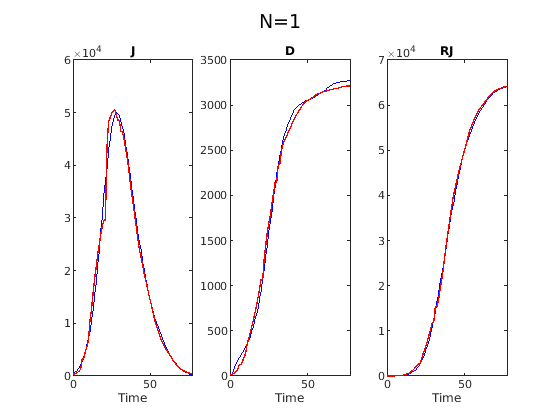

Median = median(T.Est(:,1:Filtered),2);
gsua_eval(Median,T_est,xdata,ydata);

## 5. Identification analisys

We use the following function to analyze the practical identifiability of the system for the factor families implemented to get the nominal curve (median of each factor). Also, it estimates the factors interval using a parametric methodology; for more information about it, see the main paper document.

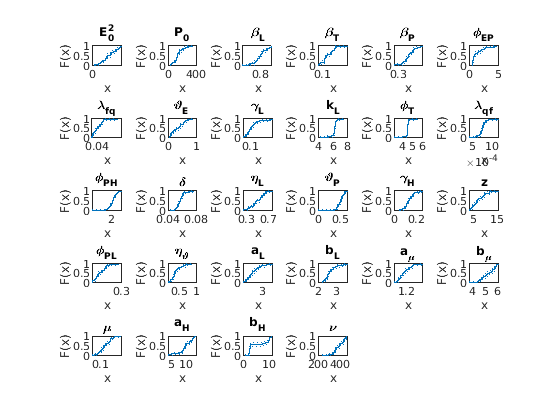

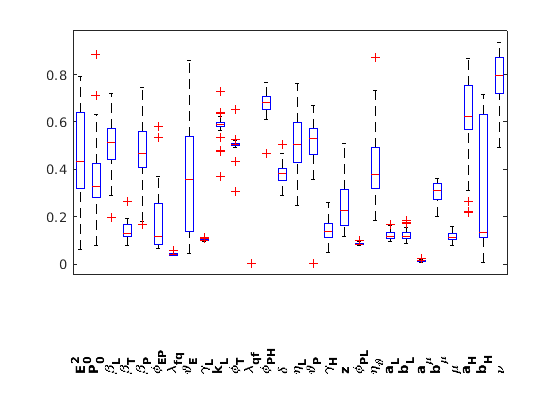

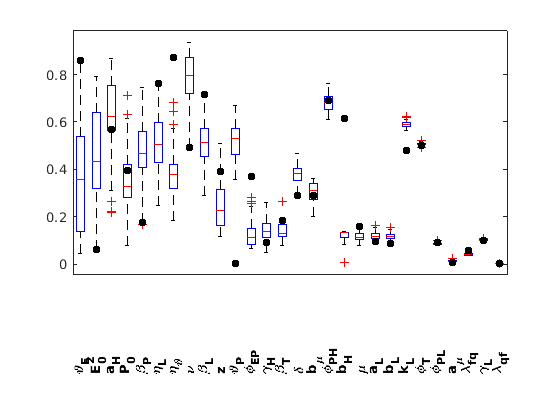

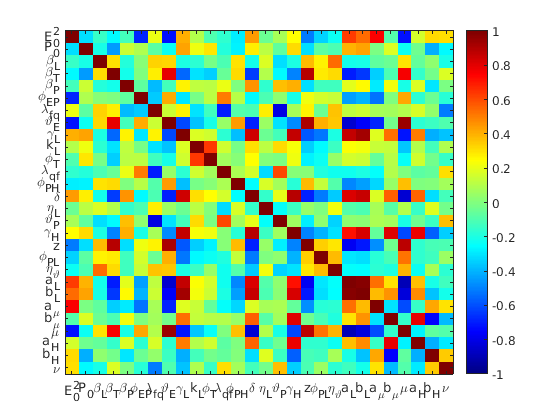

T = 28×4 table
                             Range               Nominal           Est           index  
                    ________________________    __________    ______________    ________

    E^2_0               769.17        955.18        862.17    [1×114 double]     0.20632
    P_0                 115.38         147.8        131.59    [1×114 double]     0.11307
    \beta_L            0.79725       0.80831       0.80278    [1×114 double]      0.1036
    \beta_T            0.12128       0.13959       0.13044    [1×114 double]     0.17691
    \beta_P            0.37379       0.39821         0.386    [1×114 double]    0.098067
    \phi_{EP}          0.68193        1.1527       0.91731    [1×114 double]     0.12731
    \lambda_{fq} 

T = gsua_ia(T_est, T.Est(:,1:Filtered));

## 6. Uncertainty analisys

Finally, we validate the factor intervals by performing an uncertainty analysis (Montecarlo simulations)

Number of samples and the generation of the design matrix (combination of factor values)

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).
Progress: 100%
Estimated processing time (h:m:s): 0:0:33
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:33
Estimated stop time (h:m:s): 17:11:19
Number of simulations: 1000


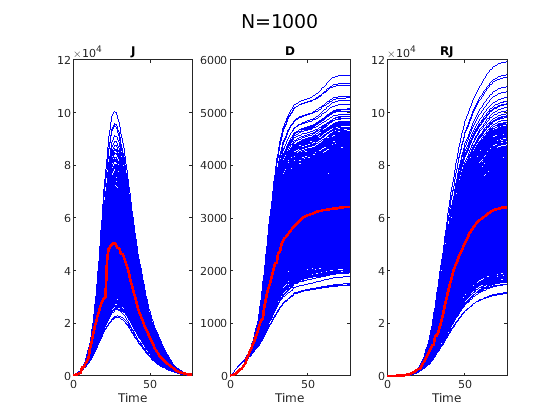

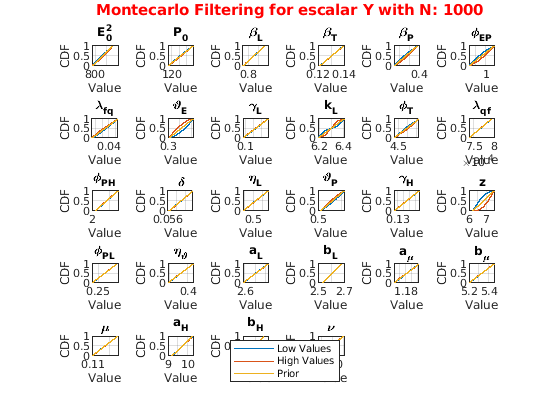

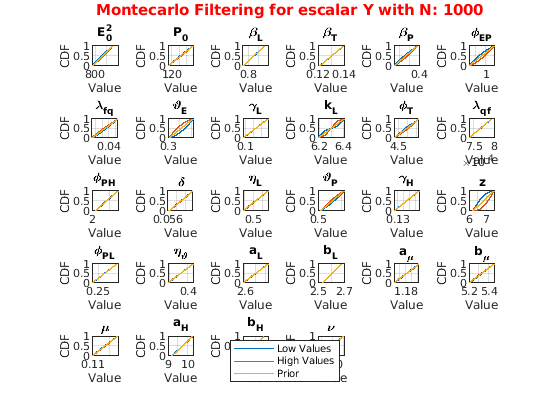

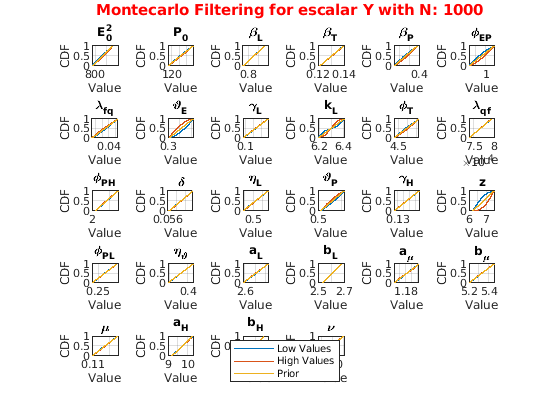

N = 1000;
M = gsua_dmatrix(T,N,'Method','Sobol');
gsua_ua(M,T,'xdata',xdata,'ynom',ydata);

Final table with estimated values and its respective confidence intervals

disp(T)

                               Range               Nominal           Est           index  
                      ________________________    __________    ______________    ________

    E^2_0                 769.17        955.18        862.17    [1×114 double]     0.20632
    P_0                   115.38         147.8        131.59    [1×114 double]     0.11307
    \beta_L              0.79725       0.80831       0.80278    [1×114 double]      0.1036
    \beta_T              0.12128       0.13959       0.13044    [1×114 double]     0.17691
    \beta_P              0.37379       0.39821         0.386    [1×114 double]    0.098067
    \phi_{EP}            0.68193        1.1527       0.91731    [1×114 double]     0.12731
    \lambda_{fq}  